# 線形回帰（単回帰分析）を1から実装して理解を深めてみよう: つづき

この記事は、MATLABアドベントカレンダー（その2）の5日目の記事として書かれています。

[https://qiita.com/advent-calendar/2022/matlab](https://qiita.com/advent-calendar/2022/matlab)

## 1 はじめに

前回の記事では、以下のように、線形回帰（単回帰分析）を行った時の、式の傾きや切片の求め方についてまとめました。

例えば、以下の図では、y = 0.33x + 50.2 という式が得られています。この傾きや切片を、xとyのペアからどのように求めるか、ということでした。

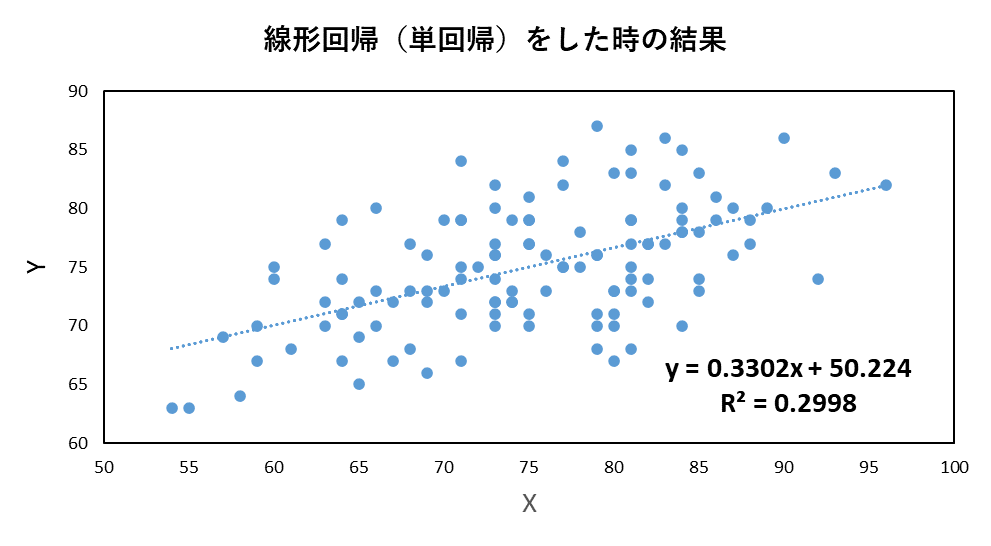

具体的には、傾きは、


$$a\;=\;\frac{\sum_{i\;=\;1}^N x_i y_i \;-\frac{1}{N}\sum_{i\;=\;1}^N x_i \;\sum_{i\;=\;1}^N y_i }{\sum_{i\;=\;1}^N {x_i }^2 -\frac{1}{N}{\left(\sum_{i\;=\;1}^N x_i \;\right)}^2 }$$


...(前回の記事の17)

であり、切片については以下の通りでした。


$$b=-\frac{1}{N}\sum_{i\;=\;1}^N x_i \;\frac{\sum_{i\;=\;1}^N x_i y_i \;-\frac{1}{N}\sum_{i\;=\;1}^N x_i \;\sum_{i\;=\;1}^N y_i }{\sum_{i\;=\;1}^N {x_i }^2 -\frac{1}{N}{\left(\sum_{i\;=\;1}^N x_i \;\right)}^2 }+\frac{1}{N}\sum_{i\;=\;1}^N y_i \;$$


...(前回の記事の18)

しかし、文量が多くなってしまい、上の図中にあるような、決定係数 $R^2$の求めかたについては、

触れられていませんでした。

そこで、本記事では、線形回帰（単回帰分析）をしたときの、決定係数の求め方について、簡単にまとめます。さらに、MATLABを用いてコーディングをし、ここでの理解による実装の結果と、MATLABのregress関数およびExcelの結果が一致することを確かめます。

## 2 決定係数の求め方について

決定係数は、以下の図の、残差を利用して求めることができます。残差とは、予測値と実測値の差のことです。

この値が小さければ小さいほど、決定係数は高くなりそうです。では、具体的にどのような式で決定係数を求めるのか見ていきたいと思います。

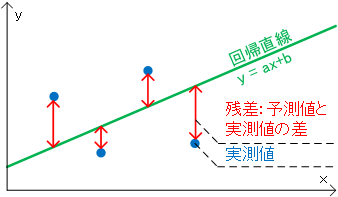

画像出展：回帰分析における寄与率(=決定係数)と、残差や相関係数との関係

https://end0tknr.hateblo.jp/entry/20170521/1495364312

### 2.1. 偏差積和を用いた傾きと切片の式の展開

#### 2.1.1. 傾きについて

以下のような、偏差積和を考えます。$\bar{x}$はxの平均です。yについても同様です。

各サンプルから、その$\bar{x}$を引き算し、yについても同様の処理を行ったものとの積を求めます。それをサンプル全体に対して行い、和を取ります。


$$T_{\mathrm{xy}} =\sum_{i=1}^N \left(x_i -\bar{x} \right)\left(y_i -\bar{y} \right)$$


...(1)

偏差積和についてはより詳しい内容を知りたい方は以下のページをご覧ください。

[https://toukeigaku-jouhou.info/2017/06/24/variance-covariance/](https://toukeigaku-jouhou.info/2017/06/24/variance-covariance/)

(1)の中身を展開して、


$$=\sum_{i=1}^N \left(x_i y_i -x_i \bar{\;y} -\bar{xy_i \;} +\bar{x\;} \bar{y} \right)$$


...(2)

各項にばらして、


$$=\sum_{i=1}^N x_i y_i \;-\sum_{i=1}^N x_i \bar{y} \;-\sum_{i=1}^N y_i \bar{x} \;+\sum_{i=1}^N \bar{x} \;\bar{y} \;$$
 

...(3)


$$=\sum_{i=1}^N x_i y_i \;-\bar{y} \sum_{i=1}^N x_i \;-\bar{x} \sum_{i=1}^N y_i \;+\sum_{i=1}^N \bar{x} \;\bar{y} \;$$
 

xの和は、xの平均と個数を掛け合わせたものと等しいので、


$$=\sum_{i=1}^N x_i y_i \;-\bar{y} N\bar{x} -\bar{x} N\bar{y} +N\bar{x} \;\bar{y}$$
 

...(4)


$$=\sum_{i=1}^N x_i y_i \;-N\bar{x} \;\bar{y}$$
 

...(5)

となります。

Σの中に戻して、


$$T_{\mathrm{xy}} =\sum_{i=1}^N x_i y_i -\frac{1}{N}\;\sum_{i\;=\;1}^N x_i \;\sum_{i\;=\;1}^N y_i \;$$


...(6)

を得ます。

傾きの式の分子に相当することがわかります。


$$a\;=\;\frac{\sum_{i\;=\;1}^N x_i y_i \;-\frac{1}{N}\sum_{i\;=\;1}^N x_i \;\sum_{i\;=\;1}^N y_i }{\sum_{i\;=\;1}^N {x_i }^2 -\frac{1}{N}{\left(\sum_{i\;=\;1}^N x_i \;\right)}^2 }$$


...(前回の記事の17)

次に、aの式の分母について考えます。

式(1)において、x = y であるとします。すると以下の等式が成り立ちます。


$$\sum_{i=1}^N x_i x_i -\frac{1}{N}\;\sum_{i\;=\;1}^N x_i \;\sum_{i\;=\;1}^N x_i =\sum_{i=1}^N \left(x_i -\bar{x} \right)\left(x_i -\bar{x} \right)\;$$


...(7)

式を整理すると、


$$\sum_{i=1}^N {x_i }^2 -\frac{1}{N}\;{\left(\sum_{i\;=\;1}^N x_i \;\right)}^2 =\sum_{i=1}^N {\left(\left(x_i -\bar{x} \right)\right)}^2$$


...(8)

となります。この左辺の式はaの分母と等しいことがわかります。

そのため、aは以下のように書き換えることができます。


$$=\frac{\sum_{i=1}^N \left(x_i -\bar{x} \right)\left(y_i -\bar{y} \right)}{\sum_{i=1}^N {\left(x_i -\bar{x} \right)}^2 }$$


...(9)

偏差積和を$T_{\mathrm{xy}}$のように表すとすると、


$$=\frac{T_{\mathrm{xy}} }{T_{\mathrm{xx}} }$$


...(10)

のように表せます。

さらに、偏差積和をサンプル数で割ると、共分散になるため、


$$=\frac{T_{\mathrm{xy}} \times \frac{1}{N}}{T_{\mathrm{xx}} \times \frac{1}{N}}$$


...(11)


$$=\frac{S_{\mathrm{xy}} }{S_{\mathrm{xx}} }$$


...(12)

とすることができます。ここでは、共分散を$S_{\mathrm{xy}}$のように表しています。

なお、式(10)から(12)にて扱ったような、共分散については以下のページがわかりやすかったです。

**共分散の意味と簡単な求め方**

[https://manabitimes.jp/math/853](https://manabitimes.jp/math/853)

#### 2.1.2. 切片について

切片は以下のようになるのでした。


$$b=-\frac{1}{N}a\sum_{i\;=\;1}^N x_i \;+\frac{1}{N}\sum_{i\;=\;1}^N y_i \;$$


...(前回の記事の14)

aにさきほどの12式の結果を代入します。


$$b=-\frac{1}{N}\frac{S_{\mathrm{xy}} }{S_{\mathrm{xx}} }\sum_{i\;=\;1}^N x_i \;+\frac{1}{N}\sum_{i\;=\;1}^N y_i \;$$


...(13)

一項目と二項目を入れ替えます。


$$=\frac{1}{N}\sum_{i\;=\;1}^N y_i -\frac{1}{N}\sum_{i\;=\;1}^N x_i \;\times \;\frac{S_{\mathrm{xy}} }{S_{\mathrm{xx}} }$$


...(14)

$\frac{1}{N}\sum_{i\;=\;1}^N x_i \;=\;$$\bar{x}$ という関係であるため、


$$=\bar{y} -\frac{S_{\mathrm{xy}} }{S_{\mathrm{xx}} }\;\bar{x} \;\;$$
 

...(15)

であることが言えます。

これにより、傾きと切片の式がかなり見やすくなりました。

決定係数を求めるために、最後の準備を行います。

### 2.2. 平方和の分解

y = ax+bの式では、xが大きくなるほど、yの値もaxだけ大きくなります。もし、この回帰式が完全である場合、yの変動は、xの変動によって

完全にカバーすることができます。しかし、実際は、ノイズなどの影響で、完全な式は得られることはなく、そのxの変動では説明できない部分が発生してしまいます。この説明できない部分が小さいほどうれしいです。では、このxの変動によって説明される部分と、説明されない部分をどのように切り分けるとよいでしょうか。

はじめに、

$y_i$ の平均回りの変動（平方和 ）は、説明変数 $y_i$ の変動によって説明される部分と、説明できない残差の平方和に分解することができます。

実際に計算していきます。$y_i$ の平均回りの変動（平方和 ）は以下の通りです。


$$S_{\mathrm{yy}} \;\mathrm{＝}\;\sum_{i\;=\;1}^N {\left(y_i -\bar{y} \right)}^2$$


...(16)


$$=\;\sum_{i\;=\;1}^N {\left\lbrace y_i -\left({ax}_i +b\right)+\left({ax}_i +b\right)-\bar{y} \right\rbrace }^2$$



$$=\;\sum_{i\;=\;1}^N {\left\lbrace y_i -\left({ax}_i +b\right)\right\rbrace }^2 +\;\sum_{i\;=\;1}^N {\left\lbrace \left({ax}_i +b\right)-\bar{y} \right\rbrace }^2 +2\sum_{i\;=\;1}^N \left\lbrace y_i -\left({ax}_i +b\right)\right\rbrace \left\lbrace \left({ax}_i +b\right)-\bar{\left.y\right\rbrace } \right.$$



$$\sum_{i\;=\;1}^N \left\lbrace y_i -\left({ax}_i +b\right)\right\rbrace \left\lbrace \left({ax}_i +b\right)-\bar{\left.y\right\rbrace } \right.$$



$$e_i =y_i -\left({ax}_i +b\right)\;$$



$$\sum_{i\;=\;1}^N e_i =0$$



$$\sum_{i\;=\;1}^N e_i x_i =0$$



$$\sum_{i\;=\;1}^N e_i \left\lbrace \left({ax}_i +b\right)-\bar{\left.y\right\rbrace } \right.$$



$$=\left(b-\bar{y} \right)\sum_{i\;=\;1}^N e_i +a\;\sum_{i\;=\;1}^N e_i x_{i\;} =0$$

$$\;$$



$$=\;\sum_{i\;=\;1}^N {\left\lbrace y_i -\left({ax}_i +b\right)\right\rbrace }^2 +\;\sum_{i\;=\;1}^N {\left\lbrace \left({ax}_i +b\right)-\bar{y} \right\rbrace }^2$$



$$\sum_{i\;=\;1}^N {\left\lbrace y_i -\left({ax}_i +b\right)\right\rbrace }^2 \;$$


平均点を通るので


$$＝\;\sum_{i\;=\;1}^N {\left\lbrace y_i -\bar{y} -a\left(x-\bar{x} \right)\right\rbrace }^2 \;$$



$$＝\;\sum_{i\;=\;1}^N {\left(y_i -\bar{y} \right)}^2 -2a\sum_{i\;=\;1}^N \left(x_i -\bar{x} \right)\left(y_i -\bar{y} \right)+a^2 \sum_{i\;=\;1}^N {\left(x_i -\bar{x} \right)}^2$$


*a*を１つだけ展開


$${=\;S}_{\mathrm{yy}} -2aS_{\mathrm{xy}} +a\frac{S_{\mathrm{xy}} }{S_{\mathrm{xx}} }S_{\mathrm{xx}}$$



$${=\;S}_{\mathrm{yy}} -aS_{\mathrm{xy}}$$
　　　　    　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　
$${\;S}_{\mathrm{yy}} =aS_{\mathrm{xy}} +{\;S}_e$$



$${\;S}_{\mathrm{yy}} ={\;S}_e +S_R$$
　　


$$S_R =\sum_{i\;=\;1}^N {\left\lbrace \left({ax}_i +b\right)-\bar{y} \right\rbrace }^2$$
　　　　　　　　　　


$$=aS_{\mathrm{xy}}$$


= $\frac{{S_{\mathrm{xy}} }^2 }{S_{\mathrm{xx}} }$


$$R^2 =\frac{S_R }{{\;S}_{\mathrm{yy}} }=\frac{S_{\mathrm{yy}} -S_e }{{\;S}_{\mathrm{yy}} }=1-\frac{S_e }{{\;S}_{\mathrm{yy}} }$$



$$R^2 =\frac{S_R }{{\;S}_{\mathrm{yy}} }=\frac{\frac{{S_{\mathrm{xy}} }^2 }{S_{\mathrm{xx}} }}{{\;S}_{\mathrm{yy}} }={\left(\frac{S_{\mathrm{xy}} }{\sqrt{S_{\mathrm{xx}} S_{\mathrm{yy}} }}\right)}^2 \;={r_{\mathrm{xy}} }^2 \;$$


load examgrades

yとXの値を設定します。

y = grades(:,5);
X = [ones(size(grades(:,1))) grades(:,1)];

regress関数で単回帰分析を行います。

[mdl,~,r,rint,stats] = regress(y,X);
disp(strcat('R2_MATLAB= ',string(stats(1))))

x = grades(:,1);
bunshi_a = sum(x.*y)-1/numel(x)*sum(x)*sum(y);

R^2=0.2998


bumbo_a = sum(x.^2)-1/numel(x)*(sum(x)^2);
a = bunshi_a/bumbo_a;
b = -1/numel(x)*sum(x)*a+1/numel(x)*sum(y);
SR = sum((a*x+b-mean(y)).^2);
Syy = sum((y-mean(y)).^2);
R2 = SR/Syy

R2 = 0.2998